
% Зчитування файлу зображення
image = imread("colorbar.png"); 

%Оброблення цифрового представлення зображення
r_layer = image(:,:,1); %червоний колір
g_layer = image(:,:,2); %зелений колір
b_layer = image(:,:,3); %синій колір

% Перехід до координа толькору у просторі RGB
r = double(r_layer(200,:))./255;
g = double(g_layer(200,:))./255;
b = double(b_layer(200,:))./255;

% Реальне зображення для визначення корегуючих коефіцієнтів
stream_image = imread("picfromtelegram.png"); 

% Обробка цифрового представлення зображення
r_layer1 = stream_image(:,:,1); %червоний колір
g_layer1 = stream_image(:,:,2); %зелений колір
b_layer1 = stream_image(:,:,3); %синій колір

% Перехід до координа толькору у просторі RGB
stream_r = double(r_layer1(200,:))./255;
stream_g = double(g_layer1(200,:))./255;
stream_b = double(b_layer1(200,:))./255;

% Визначення похибор при передаванні кольорів
%    w   ye  c   g   m   r   b
frt=[54 160 280 380 510 640 750];
scd=[157 430 810 1150 1480 1810 2180];

for i=1:1:7
   error_r(i) = r(frt(i))-stream_r(scd(i));
   error_g(i) = g(frt(i))-stream_g(scd(i));
   error_b(i) = b(frt(i))-stream_b(scd(i));

end

% Області належності корегучих коефіціентів (xyz)
B=[0.15 0.20 0.35 0.27 0.15  ; 0.06 0.17 0.37 0.13 0.06];
C =[0.20 0.27  0.35 0.20     ;0.17 0.47 0.37 0.17];
G=[0.27 0.3 0.40  0.35 0.27  ;0.47 0.6 0.53 0.37 0.47];
Ye=[0.35 0.38 0.55 0.35      ; 0.37 0.53 0.43 0.37];
R=[0.35 0.55 0.63 0.5 0.35   ; 0.37 0.4 0.33 0.24 0.37];
M=[0.27 0.35 0.5 0.27        ; 0.13 0.37 0.24 0.13];

str_r = double(r_layer1(:,:))./255;
str_g = double(g_layer1(:,:))./255;
str_b = double(b_layer1(:,:))./255;

for i=430%1:1:length(str_b(:,1))
    iiiiii=i
    for j=430%1:1:length(str_b(1,:))
        % Перехід від координт кольору зображення rgb до xyz задля того щоб
        % визначити приналежність до однієї з областей
       xyz_c=rgb2xyz([str_r(i,j) str_g(i,j),str_b(i,j)]);
       x=xyz_c(1);
       y=xyz_c(2);
       z=xyz_c(3);
       q=(x+y+z);
       x=x/q;
       y=y/q;
       z=z/q;

       % blue
       [in,on] = inpolygon(x,y,B(1,:),B(2,:));
       if in>=1 || on>=1
           str_r(i,j)=str_r(i,j)+error_r(7);
           str_g(i,j)=str_g(i,j)+error_g(7);
           str_b(i,j)=str_b(i,j)+error_b(7);
       else
           str_r(i,j)=str_r(i,j); str_g(i,j)=str_g(i,j); str_b(i,j)=str_b(i,j);
       end

       % cian
       [in,on] = inpolygon(x,y,C(1,:),C(2,:));
       if in>=1 || on>=1
           str_r(i,j)=str_r(i,j)+error_r(3);
           str_g(i,j)=str_g(i,j)+error_g(3);
           str_b(i,j)=str_b(i,j)+error_b(3);
       else
           str_r(i,j)=str_r(i,j); str_g(i,j)=str_g(i,j); str_b(i,j)=str_b(i,j);
       end

       % green
       [in,on] = inpolygon(x,y,G(1,:),G(2,:));
       if in>=1 || on>=1
           str_r(i,j)=str_r(i,j)+error_r(4);
           str_g(i,j)=str_g(i,j)+error_g(4);
           str_b(i,j)=str_b(i,j)+error_b(4);
       else
           str_r(i,j)=str_r(i,j); str_g(i,j)=str_g(i,j); str_b(i,j)=str_b(i,j);
       end

       % yellow
       [in,on] = inpolygon(x,y,Ye(1,:),Ye(2,:))
       
       if in>=1 || on>=1
           str_r(i,j)=str_r(i,j)+error_r(2)
           str_g(i,j)=str_g(i,j)+error_g(2)
           str_b(i,j)=str_b(i,j)+error_b(2)
       else
           str_r(i,j)=str_r(i,j); str_g(i,j)=str_g(i,j); str_b(i,j)=str_b(i,j);
       end
       % red
       [in,on] = inpolygon(x,y,R(1,:),R(2,:));
       if in>=1 || on>=1
           str_r(i,j)=str_r(i,j)+error_r(6);
           str_g(i,j)=str_g(i,j)+error_g(6);
           str_b(i,j)=str_b(i,j)+error_b(6);
       else
           str_r(i,j)=str_r(i,j); str_g(i,j)=str_g(i,j); str_b(i,j)=str_b(i,j);
       end
       % magenta
       [in,on] = inpolygon(x,y,M(1,:),M(2,:))
       if in>=1 || on>=1
           str_r(i,j)=str_r(i,j)+error_r(5);
           str_g(i,j)=str_g(i,j)+error_g(5);
           str_b(i,j)=str_b(i,j)+error_b(5);
       else
           str_r(i,j)=str_r(i,j); str_g(i,j)=str_g(i,j); str_b(i,j)=str_b(i,j);
       end


    end
end

iiiiii = 430

in = logical
   1


on = logical
   0


iiii = 2

str_r =     0.2549    0.2549    0.2353    0.2431    0.2549    0.2667    0.2588    0.2824    0.2824    0.2706    0.2392    0.2784    0.2824    0.2627    0.2314    0.2196    0.2353    0.2706    0.2588    0.2196    0.2471    0.2627    0.2941    0.2941    0.2745    0.2627    0.2627    0.2627    0.2667    0.2353    0.2392    0.2627    0.2588    0.2196    0.2549    0.2314    0.2667    0.2392    0.2667    0.2706    0.2706    0.2706    0.2824    0.2510    0.2549    0.2863    0.2902    0.2941    0.2902    0.2902
    0.2667    0.2431    0.2784    0.2549    0.2431    0.2471    0.3059    0.3137    0.3059    0.2627    0.2824    0.2667    0.2980    0.2784    0.2745    0.2431    0.2471    0.2627    0.2627    0.2824    0.3137    0.3059    0.3176    0.2902    0.2784    0.2549    0.2510    0.2863    0.2941    0.2902    0.2863    0.2627    0.2588    0.2941    0.2706    0.3059    0.2824    0.2353    0.2549    0.2824    0.2863    0.2627    0.3020    0.2980    0.3333    0.3176    0.3020    0.2863    0.3569 

str_g =     0.2549    0.2549    0.2353    0.2392    0.2471    0.2471    0.2392    0.2627    0.2627    0.2510    0.2196    0.2588    0.2627    0.2431    0.2196    0.2118    0.2235    0.2627    0.2471    0.2118    0.2392    0.2549    0.2863    0.2824    0.2667    0.2549    0.2549    0.2510    0.2588    0.2235    0.2314    0.2627    0.2549    0.2118    0.2431    0.2275    0.2627    0.2353    0.2627    0.2667    0.2667    0.2627    0.2706    0.2275    0.2314    0.2627    0.2667    0.2706    0.2667    0.2667
    0.2627    0.2392    0.2745    0.2510    0.2314    0.2275    0.2863    0.2941    0.2863    0.2431    0.2627    0.2471    0.2784    0.2588    0.2510    0.2196    0.2235    0.2392    0.2392    0.2588    0.2902    0.2863    0.2980    0.2745    0.2706    0.2471    0.2431    0.2784    0.2784    0.2706    0.2667    0.2392    0.2392    0.2706    0.2471    0.2863    0.2745    0.2235    0.2392    0.2627    0.2667    0.2431    0.2745    0.2706    0.3059    0.2902    0.2745    0.2588    0.3294 

str_b =     0.2471    0.2471    0.2275    0.2314    0.2431    0.2510    0.2431    0.2667    0.2667    0.2549    0.2235    0.2627    0.2667    0.2471    0.2353    0.2235    0.2353    0.2745    0.2627    0.2235    0.2431    0.2588    0.2902    0.2863    0.2706    0.2588    0.2588    0.2549    0.2627    0.2275    0.2353    0.2627    0.2588    0.2314    0.2627    0.2471    0.2824    0.2588    0.2824    0.2863    0.2863    0.2824    0.2902    0.2431    0.2471    0.2784    0.2824    0.2863    0.2824    0.2824
    0.2549    0.2314    0.2667    0.2431    0.2275    0.2314    0.2902    0.2980    0.2902    0.2471    0.2667    0.2510    0.2824    0.2627    0.2667    0.2353    0.2392    0.2549    0.2549    0.2745    0.3059    0.2902    0.3020    0.2784    0.2745    0.2510    0.2471    0.2824    0.2824    0.2745    0.2706    0.2549    0.2549    0.2980    0.2706    0.3098    0.2941    0.2431    0.2588    0.2824    0.2902    0.2667    0.3020    0.2863    0.3216    0.3059    0.2902    0.2745    0.3451 

in = logical
   0


on = logical
   0


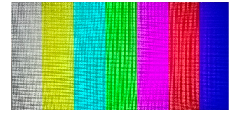


image_correct=cat(3,str_r,str_g,str_b);
imshow(image_correct)